# Actividad 6: Modelado de Energía Cinética

Ana Itzel Hernández Garía A01737526

**Obtener **el modelo de la energía cinética total para cada una de las siguientes configuraciones de robots manipuladores

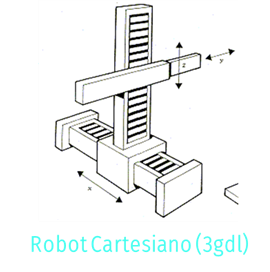

## Cartesiano

Limpieza de pantalla

clear all
close all
clc

Declaración de variables simbólicas

syms l1(t) l2(t) l3(t) t   %Angulos de cada articulación
syms l1p(t) l2p(t)  l3p(t)  %Velocidades de cada articulación
syms l1pp(t) l2pp(t) l3pp(t) %Aceleraciones de cada articulación
syms m1 m2 m3 Ixx1 Iyy1 Izz1 Ixx2 Iyy2 Izz2 Ixx3 Iyy3 Izz3  %Masas y matrices de Inercia
syms lc1 lc2 lc3 %l=longitud de eslabones y lc=distancia al centro de masa de cada eslabón
syms pi g a cero 

Vector de coordenadas articulares

Q= [l1; l2; l3];

Vector de velocidades articulares

Qp= [l1p; l2p; l3p];
Qp=Qp(t);

Creamos el vector de aceleraciones articulares

Qpp= [l1pp; l2pp; l3pp];

Configuración del robot (0 para junta rotacional, 1 para junta prismática)

RP=[1 1 1];

Número de grado de libertad del robot

GDL= size(RP,2);
GDL_str= num2str(GDL);

### Articulación 1

Posición de la articulación 1 respecto a 0

P(:,:,1)= [0;
           0;
           l1];

Matriz de rotación de la junta 1 respecto a 0

R(:,:,1)= [0  0  1 ;
           0  1  0 ;
          -1  0  0];

### Articulación 2

Posición de la articulación 2 respecto a 1

P(:,:,2)= [0; 
           0;
           l2];

Matriz de rotación de la junta 1 respecto a 0

R(:,:,2)= [1  0   0;
           0  0  -1;
           0  1   0];

### Articulación 3

Posición de la articulación 3 respecto a 2

P(:,:,3)= [0; 
           0; 
           l3];

Matriz de rotación de la junta 1 respecto a 0

R(:,:,3)=   [1  0  0;
             0  1  0;
             0  0  1];

Vector de ceros

Vector_Zeros= zeros(1, 3);

### Matrices

Inicializamos las matrices de transformación Homogénea locales

A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

Inicializamos las matrices de transformación Homogénea globales

T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

Inicializamos las posiciones vistas desde el marco de referencia inercial

PO(:,:,GDL)= P(:,:,GDL); 

Inicializamos las matrices de rotación vistas desde el marco de referencia inercial

RO(:,:,GDL)= R(:,:,GDL); 


for i = 1:GDL
    i_str= num2str(i);
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    T(:,:,i)= simplify(T(:,:,i));

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);

end

### Velocidades para el eslabón 3

#### Calculamos el jacobiano y angular lineal de forma analítica

Inicializamos jacobianos analíticos 

Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
    elseif RP(k)==1 
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

#### SubMatrices de Jacobianos

Jacobiano lineal obtenido de forma analítica

Jv_a= simplify (Jv_a);

Jacobiano ángular obtenido de forma analítica

Jw_a= simplify (Jw_a);

Matriz de Jacobiano Completa

Jac= [Jv_a;
      Jw_a];
Jacobiano= simplify(Jac)

$$Jacobiano = \left(\begin{array}{ccc} 0 & 1 & 0\\ 0 & 0 & -1\\ 1 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

#### Vectores de Velocidades Lineales y Angulares

Velocidad lineal

disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 3'); V3=simplify (Jv_a*Qp)

Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 3


$$V3 = \left(\begin{array}{c} \mathrm{l2p}\left(t\right)\\ -\mathrm{l3p}\left(t\right)\\ \mathrm{l1p}\left(t\right) \end{array}\right)$$

Velocidad angular

disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 3'); W3=simplify (Jw_a*Qp)

Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 3


$$W3 = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

### Velocidades para eslabón 2

#### Calculamos el jacobiano lineal y angular de forma analítica

Inicializamos jacobianos analíticos 

Jv_a2(:,GDL-1)=PO(:,:,GDL-1);
Jw_a2(:,GDL-1)=PO(:,:,GDL-1);

for k= 1:GDL-1
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a2(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL-1)-PO(:,:,k-1));
            Jw_a2(:,k)= RO(:,3,k-1);
        catch
            Jv_a2(:,k)= cross([0,0,1], PO(:,:,GDL-1));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a2(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a2(:,k)= RO(:,3,k-1);
        catch
            Jv_a2(:,k)=[0,0,1];
        end
            Jw_a2(:,k)=[0,0,0];
     end
 end    

#### SubMatrices de Jacobianos

Jacobiano lineal obtenido de forma analítica

Jv_a2= simplify (Jv_a2);

Jacobiano ángular obtenido de forma analítica

Jw_a2= simplify (Jw_a2);

Matriz de Jacobiano Completa

Jac2= [Jv_a2;Jw_a2];
Jacobiano2 = simplify(Jac2);

#### Vectores de velocidades lineales y angulares para el eslabón 2

Velocidad lineal

disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 2');

Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 2


V2=simplify (Jv_a2*Qp(1:2)); V2

$$V2 = \left(\begin{array}{c} \mathrm{l2p}\left(t\right)\\ 0\\ \mathrm{l1p}\left(t\right) \end{array}\right)$$

Velocidad angular

disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 2');

Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 2


W2=simplify (Jw_a2*Qp(1:2)); W2

$$W2 = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

### Velocidades para eslabón 1

Calculamos el jacobiano lineal y angular de forma analítica

Jv_a1(:,GDL-2)=PO(:,:,GDL-2);
Jw_a1(:,GDL-2)=PO(:,:,GDL-2);

for k= 1:GDL-2
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a1(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL-2)-PO(:,:,k-1));
            Jw_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)= cross([0,0,1], PO(:,:,GDL-2));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a1(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)=[0,0,1];
        end
            Jw_a1(:,k)=[0,0,0];
     end
 end    


#### SubMatrices de Jacobianos

Jacobiano lineal obtenido de forma analítica

Jv_a1= simplify (Jv_a1);

Jacobiano ángular obtenido de forma analítica

Jw_a1= simplify (Jw_a1);

Matriz de Jacobiano Completa

Jac1= [Jv_a1;
      Jw_a1];
Jacobiano1= simplify(Jac1);

#### Vectores de velocidades lineales y angulares para el eslabón 1

Velocidad lineal

disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 1');

Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 1


V1=simplify (Jv_a1*Qp(1)); V1

$$V1 = \left(\begin{array}{c} 0\\ 0\\ \mathrm{l1p}\left(t\right) \end{array}\right)$$

Velocidad angular

disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 1');

Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 1


W1=simplify (Jw_a1*Qp(1)); W1

$$W1 = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

### Energía Cinética

Distancia del origen del eslabón a su centro de masa

#### Vectores de posición respecto al centro de masa

P01=subs(P(:,:,1), l1, lc1);%La función subs sustituye l1 por lc1 en 
P12=subs(P(:,:,2), l2, lc2); %la expresión P(:,:,1)/2
P23=subs(P(:,:,3), l3, lc3);

#### Matrices de inercia para cada eslabón

Eslabón 1

I1=[Ixx1 0 0; 
    0 Iyy1 0; 
    0 0 Izz1]; 

Eslabón 2

I2=[Ixx2 0 0; 
    0 Iyy2 0; 
    0 0 Izz2];

Eslabón 3

I3=[Ixx3 0 0; 
    0 Iyy3 0; 
    0 0 Izz3]; 

#### **Función de energía cinética**

Extraemos las velocidades lineales del efector final en cada eje

Vx= V3(1,1);
Vy= V3(2,1);
Vz= V3(3,1);

Extraemos las velocidades angular del efector final en cada ángulo de Euler

W_pitch= W3(1,1);
W_roll= W3(2,1);
W_yaw= W3(3,1);

### Energía cinética para cada uno de los eslabones

#### Eslabón 1

V1_Total= V1+cross(W1,P01);
K1= (1/2*m1*(V1_Total))'*((V1_Total)) + (1/2*W1)'*(I1*W1);
disp('Energía Cinética en el Eslabón 1');

Energía Cinética en el Eslabón 1


K1= simplify (K1);

#### Eslabón 2

V2_Total= V2+cross(W2,P12);
K2= (1/2*m2*(V2_Total))'*((V2_Total)) + (1/2*W2)'*(I2*W2);
disp('Energía Cinética en el Eslabón 2');

Energía Cinética en el Eslabón 2


K2= simplify (K2);

#### Eslabón 3

V3_Total= V3+cross(W3,P23);
K3= (1/2*m3*(V3_Total))'*((V3_Total)) + (1/2*W3)'*(I3*W3);
disp('Energía Cinética en el Eslabón 2');

Energía Cinética en el Eslabón 2


K3= simplify (K3);

K_Total= simplify (K1+K2+K3);
disp('Energía Cinética Total');

Energía Cinética Total


K_Total

$$K\_Total = \frac{\bar{m_{3}}\,\left({\left|\mathrm{l1p}\left(t\right)\right|}^{2}+{\left|\mathrm{l2p}\left(t\right)\right|}^{2}+{\left|\mathrm{l3p}\left(t\right)\right|}^{2}\right)}{2}+\frac{{\left|\mathrm{l1p}\left(t\right)\right|}^{2}\,\bar{m_{1}}}{2}+\frac{\bar{m_{2}}\,\left({\left|\mathrm{l1p}\left(t\right)\right|}^{2}+{\left|\mathrm{l2p}\left(t\right)\right|}^{2}\right)}{2}$$

### Energía potencial

Obtenemos las alturas respecto a la gravedad

h1= P01(2); %Tomo la altura paralela al eje y
h2= P12(3); %Tomo la altura paralela al eje z
h3= P23(1); %Tomo la altura paralela al eje x

Energía potencial de cada eslabón

U1=m1*g*h1

$$U1 = 0$$

U2=m2*g*h2

$$U2 = g\,{\mathrm{lc}}_{2}\,m_{2}$$

U3=m3*g*h3

$$U3 = 0$$

Calculamos la energía potencial total

U_Total= U1 + U2 +U3;

Obtenemos el Lagrangiano

Lagrangiano= simplify (K_Total-U_Total);

Modelo de Energía

H= simplify (K_Total+U_Total)

$$H = \frac{\bar{m_{3}}\,\left({\left|\mathrm{l1p}\left(t\right)\right|}^{2}+{\left|\mathrm{l2p}\left(t\right)\right|}^{2}+{\left|\mathrm{l3p}\left(t\right)\right|}^{2}\right)}{2}+\frac{{\left|\mathrm{l1p}\left(t\right)\right|}^{2}\,\bar{m_{1}}}{2}+\frac{\bar{m_{2}}\,\left({\left|\mathrm{l1p}\left(t\right)\right|}^{2}+{\left|\mathrm{l2p}\left(t\right)\right|}^{2}\right)}{2}+g\,{\mathrm{lc}}_{2}\,m_{2}$$